# Comparison of neural correlates of social interactions and theory of mind

Zizhuang Miao

This script tests and visualize the neural correlates of social interaction perception and theory of mind obtained from the online crowdsourcing study. We would like to see how similar the neural correlates across two modalities are, and the common relationship between social interaction perception and ToM across modalities.

% read first-level results
dataDir = 'C:\';
files = dir(dataDir);
fileNames = {files.name};

idx_sintText = contains(fileNames, 'SInt_text_beta');
names_sintText = fileNames(idx_sintText);
idx_sintAudio = contains(fileNames, 'SInt_audio_beta');
names_sintAudio = fileNames(idx_sintAudio);
idx_tomText = contains(fileNames, 'ToM_text_beta');
names_tomText = fileNames(idx_tomText);
idx_tomAudio = contains(fileNames, 'ToM_audio_beta');
names_tomAudio = fileNames(idx_tomAudio);

cd(dataDir)
sintText = fmri_data(names_sintText);

Using default mask: C:\ResearchSoftwares\CANLabTools\CanlabCore_fork\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 87463080 bytes
Loading image number:    90
Elapsed time is 1.149802 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 18649847  Bit rate: 24.15 bits


sintAudio = fmri_data(names_sintAudio);

Using default mask: C:\ResearchSoftwares\CANLabTools\CanlabCore_fork\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 87463080 bytes
Loading image number:    90
Elapsed time is 1.260994 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 18576338  Bit rate: 24.15 bits


tomText = fmri_data(names_tomText);

Using default mask: C:\ResearchSoftwares\CANLabTools\CanlabCore_fork\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 87463080 bytes
Loading image number:    90
Elapsed time is 1.239147 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 18608345  Bit rate: 24.15 bits


tomAudio = fmri_data(names_tomAudio);

Using default mask: C:\ResearchSoftwares\CANLabTools\CanlabCore_fork\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 87463080 bytes
Loading image number:    90
Elapsed time is 1.166524 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 18581272  Bit rate: 24.15 bits


% run t-tests, threshold at FDR q < .01, and visualize results
t_sintText = ttest(sintText);
t_sintAudio = ttest(sintAudio);
t_tomText = ttest(tomText);
t_tomAudio = ttest(tomAudio);

allps = [t_sintText.p; t_sintAudio.p; 
    t_tomText.p; t_tomAudio.p];
[pThre, ~] = FDR(allps, 0.05)

******************************************
Warning! Some p-values are zero.
FDR.m will interpret these as ineligible voxels.
If these are valid p-values, they should have some not-exactly-zero value.
******************************************


pThre = 0.0158


t_sintText = threshold(t_sintText, pThre, 'unc');


Image   1
125 contig. clusters, sizes   1 to 22600
Positive effect: 40893 voxels, min p-value: 0.00000000
Negative effect: 18595 voxels, min p-value: 0.00000000


t_sintAudio = threshold(t_sintAudio, pThre, 'unc');


Image   1
109 contig. clusters, sizes   1 to 16947
Positive effect: 41202 voxels, min p-value: 0.00000000
Negative effect: 25917 voxels, min p-value: 0.00000000


t_tomText = threshold(t_tomText, pThre, 'unc');


Image   1
 45 contig. clusters, sizes   1 to 116221
Positive effect: 90550 voxels, min p-value: 0.00000000
Negative effect: 30365 voxels, min p-value: 0.00000000


t_tomAudio = threshold(t_tomAudio, pThre, 'unc');


Image   1
 48 contig. clusters, sizes   1 to 119387
Positive effect: 93416 voxels, min p-value: 0.00000000
Negative effect: 28178 voxels, min p-value: 0.00000000


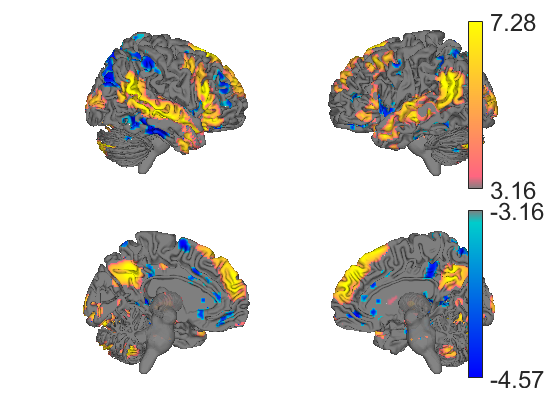

ans =   1×12 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


figure;
surface(t_sintText, 'foursurfaces')

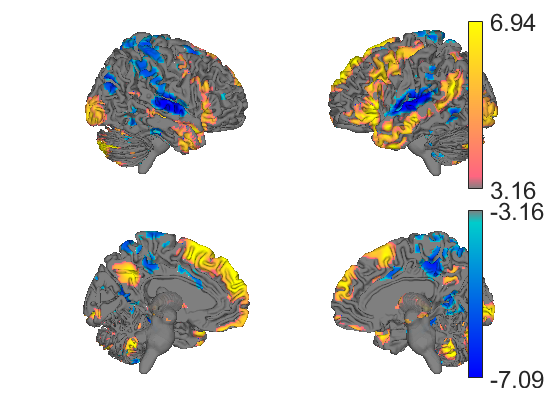

ans =   1×12 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


figure;
surface(t_sintAudio, 'foursurfaces')

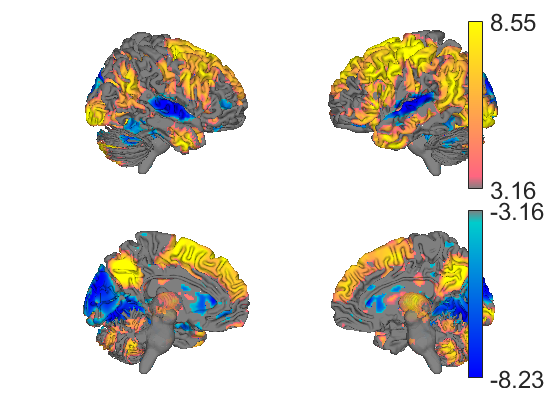

ans =   1×12 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


figure;
surface(t_tomText, 'foursurfaces')

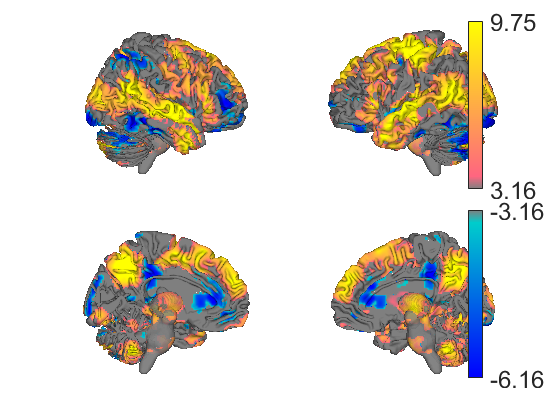

ans =   1×12 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


ans = single
0.4990

ans = single
0.5047

figure;
surface(t_tomAudio, 'foursurfaces')

Take the conjunction across modalities and visualize

t_conjTom = conjunction(t_tomAudio, t_tomText);
t_conjSint = conjunction(t_sintAudio, t_sintText);

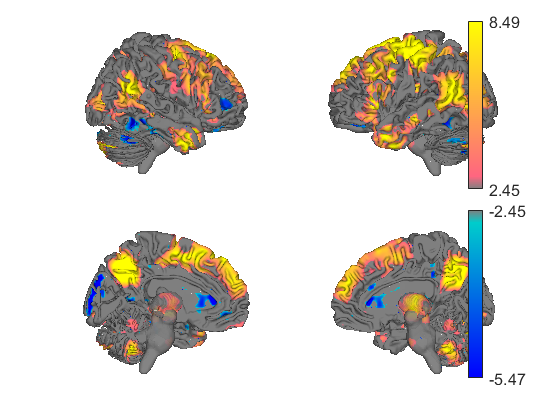

Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


ans =   1×12 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


figure;
surface(t_conjTom, 'foursurfaces')

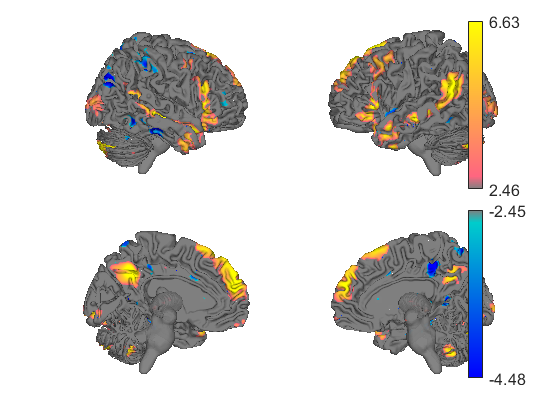

ans =   1×12 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


%figure;
surface(t_conjSint, 'foursurfaces')

corr(t_conjTom.dat, t_conjSint.dat)

ans = 0.6903

% save second-level results
saveDir = 'C:\';
write(t_sintText, 'fname', [saveDir, 'sint_text_both.nii'], 'overwrite');

Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\stats_images\sint_text_both.nii


write(t_sintAudio, 'fname', [saveDir, 'sint_audio_both.nii'], 'overwrite');

Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\stats_images\sint_audio_both.nii


write(t_conjSint, 'fname', [saveDir, 'sint_conj_both.nii'], 'overwrite', 'thresh');

Writing thresholded statistic image.
Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\stats_images\sint_conj_both.nii


write(t_tomText, 'fname', [saveDir, 'tom_text_both.nii'], 'overwrite');

Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\stats_images\tom_text_both.nii


write(t_tomAudio, 'fname', [saveDir, 'tom_audio_both.nii'], 'overwrite');

Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\stats_images\tom_audio_both.nii


write(t_conjTom, 'fname', [saveDir, 'tom_conj_both.nii'], 'overwrite', 'thresh');

Writing thresholded statistic image.
Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\stats_images\tom_conj_both.nii


Keeping vals outside of -3.219 to 3.219: 162563 voxels in .sig


Keeping vals outside of -3.219 to 3.219: 162729 voxels in .sig


Keeping vals outside of -3.219 to 3.219: 140898 voxels in .sig


Keeping vals outside of -3.219 to 3.219: 138808 voxels in .sig


ans = 15630

ans = 12

ans = 6927

Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\stats_images\sigmap_conjunction_bayesfactor_noInteraction.nii


Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat
Atlas name: CANlab_2018_combined
Coverage threshold: 25.0%


Positive Effects

         Region          Coverage    Voxels_in_region    Atlas_index_number    mean_in_region    max_abs_in_region
    _________________    ________    ________________    __________________    ______________    _________________

    {'Ctx_STSdp_L'  }     90.262            267                 257                  1                   1        
    {'Ctx_PGi_L'    }     86.881            404                 299                  1                   1        
    {'Ctx_7m_R'     }     81.224            245                  60                  1                   1        
    {'Ctx_STSvp_L'  }     79.327            208                 259                 

tableDir = 'C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\region_tables\'

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat
Atlas name: CANlab_2018_combined
Coverage threshold: 25.0%


Positive Effects

        Region        Coverage    Voxels_in_region    Atlas_index_number    mean_in_region    max_abs_in_region
    ______________    ________    ________________    __________________    ______________    _________________

    {'Ctx_2_L'   }      64.76           647                  103                  1                   1        
    {'Ctx_6d_R'  }     53.316           377                  108                  1                   1        
    {'Ctx_PFt_L' }     50.575           174                  231                  1                   1        
    {'Ctx_6mp_L' }     40.461           477                  109                  1                

tableDir = 'C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\region_tables\'

ans = 27117

ans = 2157

ans = 23269

Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\stats_images\sigmap_audio_bayesfactor_noInteraction.nii


ans = 25255

ans = 1830

ans = 27170

Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\stats_images\sigmap_text_bayesfactor_noInteraction.nii


Keeping vals outside of -3.219 to 3.219: 162563 voxels in .sig


Keeping vals outside of -3.219 to 3.219: 162729 voxels in .sig


Keeping vals outside of -3.219 to 3.219: 140898 voxels in .sig


Keeping vals outside of -3.219 to 3.219: 138808 voxels in .sig


Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\stats_images\sigmap_conjunction_bayesfactor_noInteraction.nii


ans = 15436

ans = 12

ans = 6787